# 数字图像滤波处理-DnCNN

## 1.图像噪声生成*Noise-Generating*

- 高斯噪声

- 脉冲（椒盐）噪声

## 2.图像预处理*Image-Pre-Processing*

- 图像初步处理

- GPU处理管线

## 3.数字滤波器*Digital-Filter*

- 均值滤波

- 中值滤波

- 复合滤波

## 4.实验设计*Experiment*

- 滤波效果评价标准

- 实验流程设计

## 5.统计与性能分析*Statistic&Performance*

- 降噪效果统计

- 性能分析

## 6.结论*Conclusion*

## 参考文献*Reference*

## 1.图像噪声生成*Noise-Generating*

### 1.1 高斯噪声

高斯噪声是自然界最常见的噪声。根据中心极限定理，在自然界中，一些现象受到许多相互独立的随机因素的影响，如果每个因素所产生的影响都很微小，那么总的影响可以看作是服从高斯（正态）分布的。

一般而言，对一个抗噪系统而言高斯噪声是最恶劣的噪声，设计系统时只要能够抵抗高斯噪声，那么系统性能就有保证。

一般的，高斯分布的概率密度函数由下式给出：


$$p\left(z\right)=\frac{1}{\sqrt{2\pi }\sigma }e^{-\frac{{\left(z-\mu \right)}^2 }{2\sigma^2 }}$$


- $z:$随机变量

- $\sigma :$标准差

- $\mu :$均值

特别的，标准正态分布（均值为0，标准差为1的高斯分布）将简化为如下形式：


$$p\left(z\right)=\frac{1}{\sqrt{2\pi }}e^{-\frac{z^2 }{2}}$$


在MATLAB中，通常用如下方式为图像添加高斯噪声：

output = imnoise(image,'gaussian',average,variance);

### 1.2 脉冲（椒盐）噪声

数字图像被脉冲噪声损坏，通常是由于一种具有噪声的照相机传感器和错误的模拟数字转换所造成的。椒盐噪声（salt && pepper noise）的噪声像素值为Nmin或Nmax。在灰度图像中为最小灰度值或最大灰度值，即0和255（黑白像素点）。因其很像椒盐的颜色，所以取名为椒盐噪声。

椒盐噪声定义：


$$\[ p(z)=\begin{cases}
    P_{a} \quad z\geq q \\
    P_b  \quad z<q\\
    \quad 0 \quad otherwise

\end{cases} \]$$


- $P_a$：噪声的最大灰度值

- $P_b$：噪声的最小灰度值

- $q$：噪声选择阈值

在MATLAB中，通常用如下方式为图像添加椒盐噪声：

output = imnoise(image,'salt & pepper',density_of_noise);

## 2.图像预处理*Image-Pre-Processing*

### 2.1 图像初步处理

#### 2.1.1 图像基本操作

在MATLAB中，通常以如下方式读取图片：

data = imread(path,file_type); % data变量指向内存中存有图像数据的数组

显示图片：

imshow(data); % 从数组显示图像

查看图片数据大小：

size(data);

#### 2.1.2 图像转换

将图像转为二值图：

bw_data = imbinarize(data); % 新版本中，MATLAB不再建议使用im2bw()进行二值转换

将图像转为灰度图：

grey_data = im2gray(data);

#### 2.1.3 保存图像

保存灰度图像

imwrite(gray_data,'filename');

保存彩色RGB图像

imwrite(data,'filename','jpg');

### 2.2 GPU处理管线

为了利用现代图形处理单元 (GPU) 提供的性能优势，某些图像处理函数支持在 GPU 上执行图像处理运算。这可以为复杂的图像处理工作流提供 GPU 加速。这些方法可以单独实现，也可以组合实现，以满足具体设计要求和性能目标。

GPU在进行矩阵运算时的速度远快于CPU，特别在使用深度学习相关技术时将变得尤为关键。然而只有部分函数支持在GPU上使用CUDA进行计算，因此在MATLAB中的GPU计算仍然存在诸多限制。

在MATLAB中，通常使用以下方法将数组转移至GPU Memory（即显存）中：

G = gpuArray(data);

将GPU上的数据转移回工作区（内存）中：

W = gather(G);

## 3.数字滤波器*Digital-Filter*

对于单一图像（此处暂时不讨论视频流）而言，滤波器不再工作在流式序列数据中，而是工作在矩阵数据（N维矩阵）中。因此，对滤波器的采样方式进行转变是符合直觉的。

考虑一个窗口（通常是n×n×d的张量）在图像对应的数据张量上平移，框内的元素即为被采样的数据。将被采样的数据进行计算后来代替矩阵框中心点的值，我们就完成了一次滤波的计算，此后只要我们不断平移窗口即可完成整个图像的滤波计算，这种窗口有时也被称为“卷积核”（或滤波器），尽管其运算并非数学意义上的卷积。

因此，不同的滤波算法只需改变被采样的数据对象的计算方式即可，对于非1×1的卷积核而言，图像的边界可能将无法进行滤波计算，可以考虑使用增广的方式为图像外围填充区域以应用卷积，为了简化模型，本文并不采取这样的措施。

卷积核的一种简单实现如下（省略了“function-end”关键字）：

[output]=convCore(data, filter_size, step, weights)
% data：图像数据对应的数组 
% filter_size：卷积核的大小
% step：平移的步长
% weights：卷积核内的权重，通常为一个与卷积核大小相同数组或者服从某种概率分布的权重集合，
%          非全1矩阵时可能需要进行归一化

[n,m,d] = size(data);           % 获取图像维度信息
edge = floor(filter_size/2);    % 边缘到中心点的距离
pole = [edge+1,edge+1, 1];      % 中心点初始位置
datax = data(:,:,:);            % 复制图像数组

while n >= (pole(1) + edge)     % 卷积核依次向下滑动
    while m >= (pole(2) + edge) % 卷积核依次向右滑动
        for i=0:d-1             % 对所有通道进行运算
            values = datax(pole(1)-edge:pole(1)+edge,pole(2)-edge:pole(2)+edge,pole(3)+i); 
            conv_values = values.*weights;
            %
            % 此处决定中心点取值方式
            %
            datax(pole(1),pole(2),pole(3)+i) = rep_values;
        end
        pole(2) = pole(2) + step;
    end
    pole(2) = edge + 1;
    pole(1) = pole(1) + step;
end

output = datax;

### 3.1 均值滤波

- 算术均值滤波：对采样数据取均值后替代中心点的值

- 加权均值滤波：对被采样值做加权均值后替代中心点的值

- 滑动均值滤波：可以带权值计算，不同的地方在于每次仅更新一部分被采样数据，而非全部

以上均值滤波算法事实上几乎相同，在现代图像处理中，一般都采用滑动的方式进行均值滤波，因此本文只讨论其中一种，即滑动均值滤波算法的实现（填补上文卷积核中的取值方式）：

rep_values = mean2(conv_values);

MATLAB内建方法实现：

aver_filter = fspecial('average', filter_size);
filtered_data = imfilter(data, aver_filter);

### 3.2 中值滤波

取采样数据的中位数以取代中心点的值，可以很好地对抗椒盐噪声，以下为一种实现方式（填补上文卷积核中的取值方式）：

rep_values = median(conv_values);

MATLAB内建方法实现：

filtered_data = medfilt2(data);

### 3.3 **复合滤波**

传统的滤波方式通常对图像噪声有强假设性，即使用一种滤波方式时通常需要假设图像噪点服从某种特定分布，中值滤波是一个很好的例子，在中心点对齐椒盐噪点所处的像素点时，能够很好地消除噪点，然而，这样的方式却也在一定程度上消除了图像中的边缘纹理（或者说高频信息）。另一方面，这些算法通常只能利用单张图片的信息，而这些图片的信息往往又不完全（被噪声干扰），自然无法得出更好的结果，下面将分别介绍基于这两种思路的复合或者高级滤波算法

#### **3.3.1 利用多张图像——图像堆栈**

使用多张照片进行融合的想法也被称为多帧合成（比如在一次拍摄中让CMOS连续产生多张图像，并将其合成为一张）也叫图像堆栈，是一种朴素的利用时域冗余信息的方式。常见的方式有均值堆栈或中值堆栈，将多张内容相同，品质不同的图片对齐后，对每个像素点进行一次取均值或中值（即计算所有被采样图片在该点的均值或中值）以替代该像素点的值。假设对于图像的任意一个像素可以表示为（注意此处我们将图像视为一条维度为1的长向量而不是通常的张量，以此简化表达）


$$y_i =x_i +v_i$$


- $y_i$：图像的第$i$个像素点的实际值（假设只有一个颜色通道），由真值和噪声值叠加而来

- $x_i$：该像素点的真值，即没有噪声时的值

- $v_i$：该像素点的噪声值，最常见的噪声服从高斯分布

在MATLAB计算机模拟中，添加噪声函数***“imnoise('gaussian')”***对每个像素点产生噪声$X~N\left(0,0\ldotp 01\right)$，即噪声服从数学期望为0，方差为0.01的高斯分布。由切比雪夫大数定律


$$\lim_{n\to +\infty } P\left\lbrace \left|\frac{1}{n}\sum_{i=1}^n X_i -\frac{1}{n}\sum_{i=1}^n E\left(X_i \right)\right|<\varepsilon \right\rbrace =1\;,\varepsilon >0,\;X_i \;\;\textrm{are}\;\textrm{independent}$$


可知当采样数趋近于无穷大（即选取无穷多的图像进行堆栈）时，每个像素点的噪声均值将收敛至其数学期望（也就是0），于是堆栈出的图像将趋于无噪声的图像。这也能解释为什么在低ISO时，加长曝光时间可以获得更纯净的画面，因为这么做将近似于图像堆栈。不过图像堆栈的数量总是有限的，CMOS感知的画面很难在长时间保持一致，而短时间内进行连拍则对硬件性能提出了较高的要求。

由于图像堆栈的算法较为简单，因此本节不讨论其具体实现。

#### 3.3.2 更低的假设性——卷积神经网络

#### 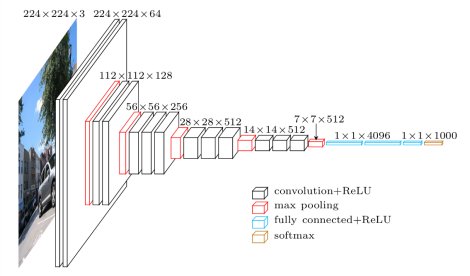

图3.3.2-1 VGG-16[1]

考虑一种能够降低假设性的算法也是符合直觉的做法。本节将简单介绍基于卷积神经网络（深度学习）构建的降噪算法——DnCNN[2]，也是将深度学习应用于图像降噪应用的最简单的算法之一。

#### 3.3.2.1 多层感知机

在介绍DnCNN之前，我们有必要快速回顾关于神经网络的基础内容。首先，我们知道经典多层感知机（MLP）的计算模型[3]：

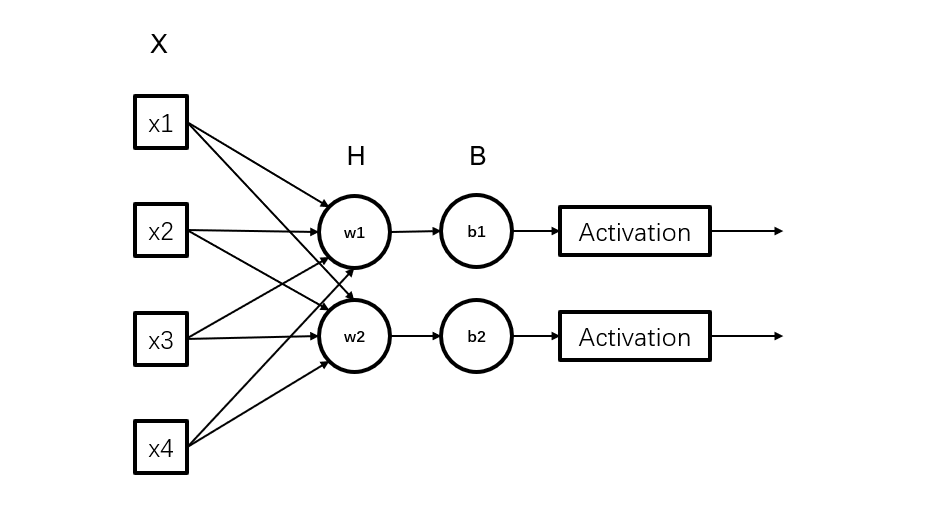

图3.3.2.1-2 多层感知机模型

- $X={\left\lbrack x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_d \right\rbrack }^T$：单个样本的输入向量（有时输入可以是多个样本），$d$为输入向量的维度

- $H={\left\lbrack w_1 ,w_2 ,\ldotp \ldotp \ldotp w_h \right\rbrack }^T$：隐藏层的隐藏单元参数，$h$为隐藏单元的数量

- $w_i ={\left\lbrack w_{i,1} ,w_{i,2} ,\ldotp \ldotp \ldotp ,w_{i,j} \right\rbrack }$：第$i$个隐藏单元的对$j$个输入通道的权重，此处$j=d$

- $B={\left\lbrack b_1 ,b_2 ,\ldotp \ldotp \ldotp ,b_h \right\rbrack }^T$：隐藏层偏置值，每个隐藏单元对应一个偏置值

- $\sigma ~\textrm{Activation}$：激活函数（通常为ReLU或者其变体，我们在之后的讨论中会知道它的优势），下文将以$\sigma$符号指代激活函数

因此它的输出是：


$$Z=\textrm{HX}+B$$



$$y=\sigma \left(Z\right)$$


假设我们的模型只有这一个隐藏层，我们设定一个损失函数：


$$L\left(\theta \right)=\frac{1}{2}||\hat{y} -y\left(\theta \right)||_2$$


- $\hat{y}$：当前训练样本的真实标签

- $y\left(\theta \right)$：给定模型参数$\theta$时，模型输出

在这个例子中可以得到：


$$H=\left\lbrack \begin{array}{c}
w_1 \\
w_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
w_{1,1}  & w_{1,2}  & w_{1,3}  & w_{1,4} \\
w_{2,1}  & w_{2,2}  & w_{2,3}  & w_{2,4} 
\end{array}\right\rbrack$$



$$X={\left\lbrack \begin{array}{cccc}
x_1  & x_2  & x_3  & x_4 
\end{array}\right\rbrack }^T$$



$$B={\left\lbrack \begin{array}{cc}
b_1  & b_2 
\end{array}\right\rbrack }^T$$



$$Z={\left\lbrack \begin{array}{cc}
z_1  & z_2 
\end{array}\right\rbrack }^T$$



$$y={\left\lbrack \begin{array}{cc}
y_1  & y_2 
\end{array}\right\rbrack }^T$$


可以得到损失函数对隐藏单元$w_1$的其中一个权重$w_{1,1}$（为书写方便，此处省略了引用参数。同时，我们只进行了一次前向传播，故不用取均值）的偏导数（梯度）为：


$$\begin{array}{l}
\frac{\partial L}{\partial w_{1,1} }=\frac{\partial L}{\partial y_1 }\frac{\partial y_1 }{\partial z_1 }\frac{\partial z_1 }{\partial w_{1,1} }\\
\;\;\;\;\;\;\;\;\;\;=\frac{\partial }{\partial y_1 }\left\lbrack \frac{1}{2}\sqrt{{\left(\hat{y_1 } -y_1 \right)}^2 }\right\rbrack \left(1\right)\left(x_1 \right)\\
\;\;\;\;\;\;\;\;\;\;=\left\lbrack \frac{1}{4}\cdot \frac{1}{\sqrt{{\left(\hat{y_1 } -y_1 \right)}^2 }}\cdot 2\left(\hat{y_1 } -y_1 \right)\cdot \left(-1\right)\right\rbrack x_1 \\
\;\;\;\;\;\;\;\;\;\;=-\frac{\hat{y_1 } -y_1 }{2\left\|\hat{y_1 } -y_1 \right\|}x_1 
\end{array}$$


比起Sigmoid函数，ReLU将极大方便求导过程,由于激活函数为ReLU，当输入值大于0时，输出值为它本身，因此$\frac{\partial y_1 }{\partial z_1 }=1$。于是我们可以更新$w_{1,1}$的权重：


$$w_{1,1} \longleftarrow w_{1,1} -\eta \frac{\partial L}{\partial w_{1,1} },\eta >0$$
 

这就完成了一次（对一个参数的）参数更新，也就是反向传播，其中$\eta$为学习率，是一个超参数。然而这只是一种最简单的情况，如果网络拥有多个隐藏层，那么求解第L层的任意一个隐藏单元的偏导数时，就必须先计算L+1层的所有偏导数（即遍历所有传播路径）。假设$y=g\left(x\right),z=f\left(y\right)$，其中$x,y$是维度为$n,m$的向量，那么对于前一层的任一偏导数就要写为求和的形式，这将递归地定义对于任意参数$x_i$的梯度[3]：


$$\frac{\partial z}{\partial x_i }=\sum_{j=1}^m \frac{\partial z}{\partial y_j }\frac{\partial y_j }{\partial x_i }$$


或者：


$$\nabla_x z={\left(\frac{\partial y}{\partial x}\right)}^T \nabla_y z$$


其中$\frac{\partial y}{\partial x}$是$g$的$n\times m$的***Jacobian矩阵。***

#### **3.3.2.2 从多层感知机到卷积层**

卷积层的引入基于以下两个归纳偏置：

- 平移等变性：无论被检测的对象（或特征）在图像中处于何种位置，造成的影响仅仅是隐藏层表示中的平移（而不是放缩或旋转等）

- 局部相关性：图像中相邻区域具有相同或相似特征

卷积层被认为是一种“权值共享”且“稀疏连接”的多层感知机（或者说全连接层）。假设输入为一个$n\times n$的图像，权值共享说明一个隐藏单元只含有若干个参数（与核的大小有关），而不像多层感知机的输入侧隐藏单元那样每个都有$n\times n$个参数（与输入规模无关）；稀疏连接意味着隐藏单元的某些输入通道将不会与图像的某些地方建立连接。因此，原来多层感知机可能需要数十亿参数来表示网络中的一层，而卷积网络则只需几百个参数，这极大提高了算法的效率。

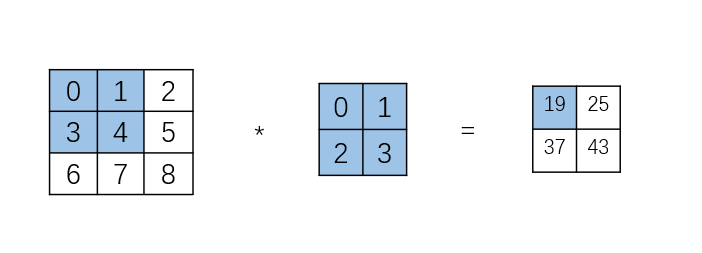

图3.3.2.2-1 互相关运算

每一层的每一个卷积核与图像中的数值做互相关运算，形成新的***特征图FeatureMap***，下一层的卷积核再对这些特征图进行互相关运算，如此反复进行，卷积核中的权值将通过反向传播进行优化。卷积层一般不会独立作用，下面将介绍一些与其协同工作的技术。

***池化层Pooling***，它本质上也是一个固定尺寸的滑动窗口，但是它只取窗口内的最大值（或平均值，取决于模型设计者）来生成特征图。池化能够将特征图的尺寸缩小，进一步聚集信息，使隐藏单元的感受野进一步增大。

***BN层（Batch-Normalization）***，或称“批量归一化”，同样是构建网络常用的层。BN的作者认为，BN层将中间层输出的那些不同量级的数据进行归一化，以进一步提升网络的收敛速度。这种归一化针对训练批量的数学期望和方差对输入数据进行放缩，并将其“居中（映射到均值为0，方差为1的分布上）”，真正的BN层还将带有放缩参数和偏移参数。实际上，关于BN层以及未提及的Dropout操作（现在已经非常少见），并没有严格理论证明其作用，但是在实验与工程中它确实有效，它适用于绝大部分的卷积神经网络。

除此以外，还有很多针对卷积神经网络进行改进的技术，如残差连接[4]等，但这已经超出了介绍DnCNN所需的知识范围。

#### 3.3.2.3 DnCNN网络

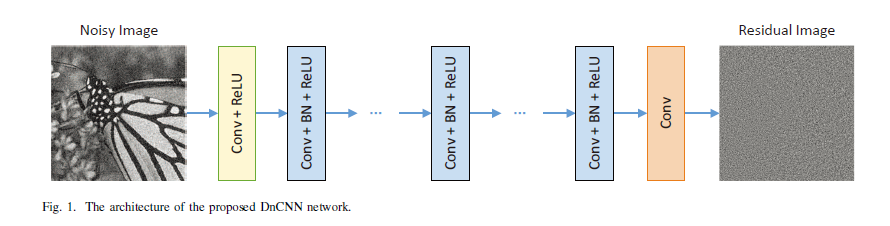

图3.3.2.3-1 DnCNN网络架构

DnCNN包含20个卷积层，每个卷积层有64个卷积核，相当于每层有64个滤波器。DnCNN接受含噪声图像$y$作为输入，再估计噪声图像$R\left(y\right)$，最后输出降噪图像$x=y-R\left(y\right)$

作者将训练数据$\left\lbrace x_{i,} y_i \right\rbrace$损失函数定义为：


$$l\left(\theta \right)=\frac{1}{2N}||R\left(y_i ;\theta \right)-\left(y_i -x_i \right)||$$


式中$\left(y_i -x_i \right)$即被估计的噪声的真值，而$R\left(y_i ;\theta \right)$为网路参数为$\theta$时对噪声图片$y_i$估计的噪声，整个损失函数为两者差值的L2范数再取样本均值，网络的优化目标就是缩小$R\left(y_i ;\theta \right)$与$\left(y_i -x_i \right)$的距离，反向传播时使用SGD或者Adam。

在MATLAB中使用DnCNN：

[nR,nG,nb] =imsplit(data); % 对图像按通道分解
net = denoisingNetwork('dncnn'); % 调用DnCNN网络
denoisedR = denoiseImage(nR,net); % 降噪过程
denoisedG = denoiseImage(nG,net);
denoisedB = denoiseImage(nB,net);
denoisedRGB = cat(3,denoisedR,denoisedG,denoisedB); % 重新合成彩色图像

需要说明的是，单张降噪与多帧合成可以一起使用，或者融合为一个算法，这种方式也是目前智能手机拍照的普遍做法，可以有效弥补传感器性能的不足（CMOS面积较小、镜头组光学性能差等）带来的问题。更前沿的算法考虑使用CMOS以外的传感器（如深度传感器等）进行多模态融合以获得更清晰完整的图像，然而，讨论多模态融合已经超出了本文的范围。

不难看出，DnCNN是一个基础网络，它主要是利用单张照片的信息进行降噪。同时，它是一种盲降噪算法，即无需得知噪声水平即可工作的算法，由此可见，DnCNN降低了对噪声的假设性。然而，性能不佳的VGG骨干网络使得DnCNN的性能在今天看来已经与SOTA有一定差距，且推理速度较慢，本文会在之后详细讨论这点。

DnCNN提出了残差学习的思路，这种思路不仅仅适用于降噪领域，也适用于超采样，感知系统等领域，是一个具有开山鼻祖性质的网络。除此以外，在视觉领域应用深度学习不止CNN一种方式，也可以是基于Transformer的网络，如ViT[5]等，同时它们也更适合做大模型迁移学习的任务。

## 4.实验设计*Experiment*

### 4.1 滤波效果评价标准

为了实验的准确性，设置一个评价滤波效果的标准是有必要的，本文以下三个指标作为衡量滤波效果的标准：

SSIM：计算降噪图像与原图的结构相似性，接近1时说明图片与参考图片相当一致，图像质量好

denoisedSSIM = ssim(denoisedRGB,pristineRGB);

PSNR：峰值信噪比，越大时说明图像质量越高

denoisedPSNR = psnr(denoisedRGB,pristineRGB);

NIQE：自然图像质量测试，是一种无参考图的图像质量测试方法。得分越低说明图像质量越高

denoisedNIQE = niqe(denoisedRGB);

### 4.2 实验流程设计

我们在97张大小不同，风格不同的图像上进行测试，所有图像的噪声水平均保持一致。使用传统方法（均值、中值滤波器）、复合方法（图像堆栈）和一种先进方法（DnCNN）对图像进行降噪，最后统计所有降噪后图像的得分。

#### 4.2.1 读取图片

clear;
[img, imglist] = loadimg('Original/');

#### 4.2.2 添加噪声

% 添加噪声
noised = addnoise(img);
saveimg(noised,imglist,'Noised/');

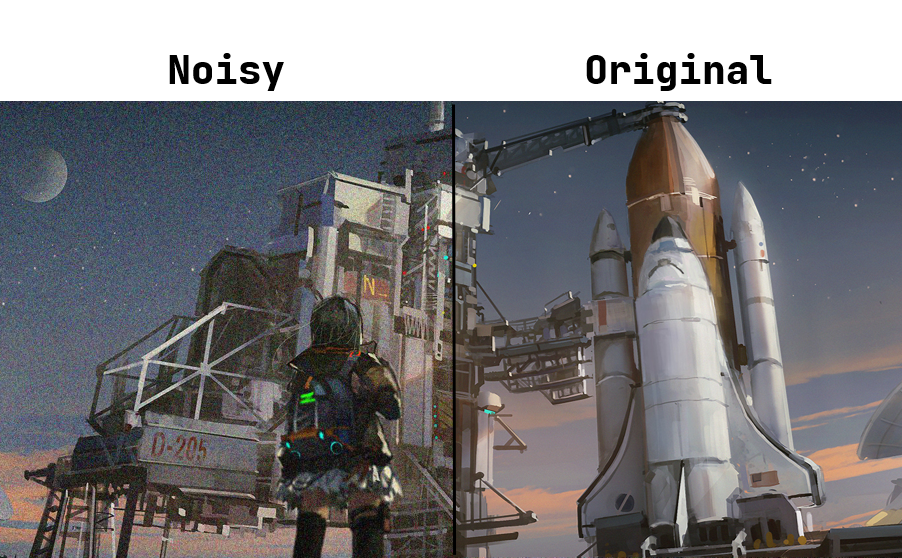

图4.2.2-1 噪声对比图

#### 4.2.3 均值滤波

cores = 3;
step = 1;
mode = 1;
isgpu = 1;
weights = gpuArray(ones(3,3,3,"uint8"));
avgImg = denoised(noised,cores,step,mode,weights,isgpu);
saveimg(avgImg,imglist,'Denoised/avg/');

#### 4.2.4 中值滤波

mode = 2;
medImg = denoised(noised,cores,step,mode,weights,isgpu);
saveimg(medImg,imglist,'Denoised/med/');

#### 4.2.5 复合滤波：DnCNN

net = denoisingNetwork('dncnn'); 
cnnImg = cnnDenoise(noised,net);

## 5.统计与性能分析*Statistic&Performance*

### 5.1 降噪效果统计

clear;
loading();
%avg_scores = scores(avg,img);

#### 5.1.1 PSNR峰值信噪比：

x = [1 2 3 4];
b1 = barh(x, [mean(avg_scores.psnr),mean(med_scores.psnr), ...
    mean(cnn_scores.psnr),mean(stack_scores.psnr)], 0.6);
xtips2 = b1(1).YEndPoints - 5;
ytips2 = b1(1).XEndPoints;
labels2 = string(b1(1).YData);
text(xtips2,ytips2,labels2,'VerticalAlignment','middle','Color','white')
yticklabels({'均值滤波','中值滤波','DnCNN','图像堆栈（5X）'});
xlabel('PSNR(dB): Higher is better')
ylabel('Algorithm');
title('PSNR Comparison');
hold off
axis([0 33 0 5]);

#### 5.1.2 SSIM结构相似度

b2 = barh(x,[mean(avg_scores.ssim),mean(med_scores.ssim), ...
    mean(cnn_scores.ssim),mean(stack_scores.ssim)],0.6);
xtips2 = b2(1).YEndPoints - 0.15;
ytips2 = b2(1).XEndPoints;
labels2 = string(b2(1).YData);
text(xtips2,ytips2,labels2,'VerticalAlignment','middle','Color','white');
yticklabels({'均值滤波','中值滤波','DnCNN','图像堆栈（5X）'});
xlabel('SSIM: Higher is better')
ylabel('Algorithm');
title('SSIM Comparison');
axis([0 1 0 5]);

#### 5.1.3 NIQE 自然图像质量

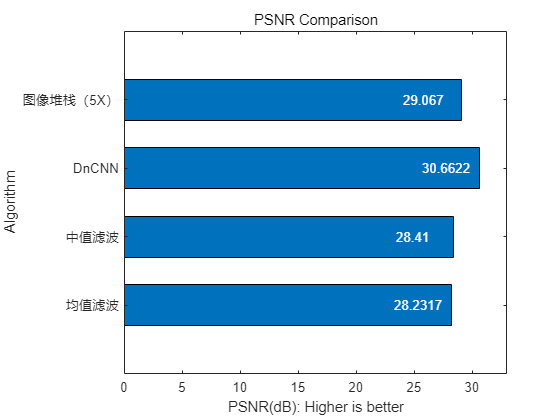

b2 = barh(x,[mean(avg_scores.niqe),mean(med_scores.niqe), ...
    mean(cnn_scores.niqe),mean(stack_scores.niqe)],0.6);
xtips2 = b2(1).YEndPoints - 0.5;
ytips2 = b2(1).XEndPoints;
labels2 = string(b2(1).YData);
text(xtips2,ytips2,labels2,'VerticalAlignment','middle','Color','white');
yticklabels({'均值滤波','中值滤波','DnCNN','图像堆栈（5X）'});

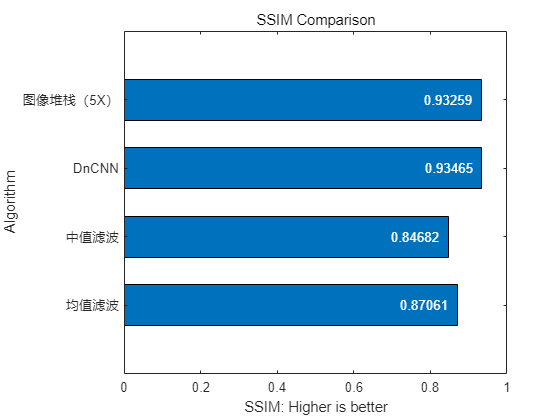

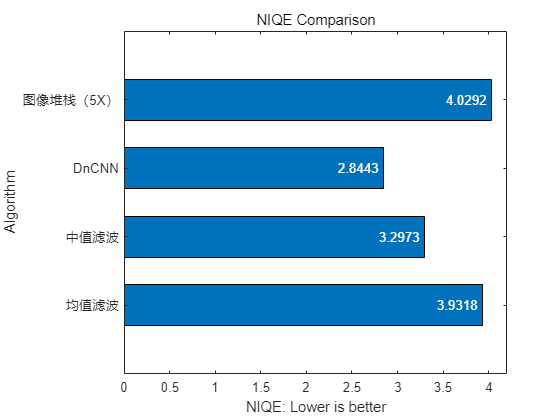

xlabel('NIQE: Lower is better')
ylabel('Algorithm');
title('NIQE Comparison');
axis([0 4.2 0 5]);

### 5.1.4 小结

通过三个性能指标的对比，不难看出，基于卷积神经网络的DnCNN算法平均比传统方法（均值、中值滤波等）提升约7~15%。在NIQE测试中，DnCNN对比其它算法的领先幅度甚至接近30%。

事实上，卷积神经网络的强大之处不只是在诸如PSNR这些性能指标上，因为这些性能指标通常只能反映图像张量的结构性信息而不能反映人眼的实际观感，而应用卷积神经网络进行降噪后的图像在人眼观感上甚至有更大幅度的领先。

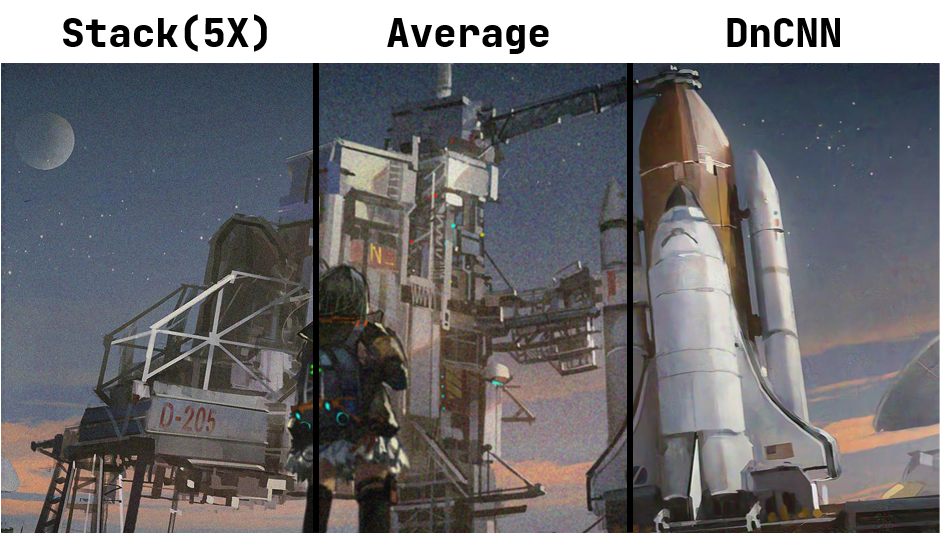

图5.1.4-1 均值滤波与DnCNN降噪效果对比

### 5.2 性能分析

一种算法能否真正被应用于实际场景中，不仅仅取决于算法本身的效果，还取决于它的性能开销。

传统方法在GPU（测试平台的FP32浮点性能约为5.5TFLOPS）上完成所有图像处理任务的平均计算时间约为1.5s（不计I/O时间），而DnCNN在GPU上的推理速度则约为1s/张（使用MATLAB的速度将达到25s以上每张，因为MATLAB的DnCNN模型无法运行在GPU上），这花费了传统方法近100倍的时间。

不仅仅是时间开销，DnCNN使用的Backbone为VGG网络，这带来了巨大的显存负担，包括显存的带宽瓶颈、容量瓶颈等。这一切都将被算入我们的开销之中。

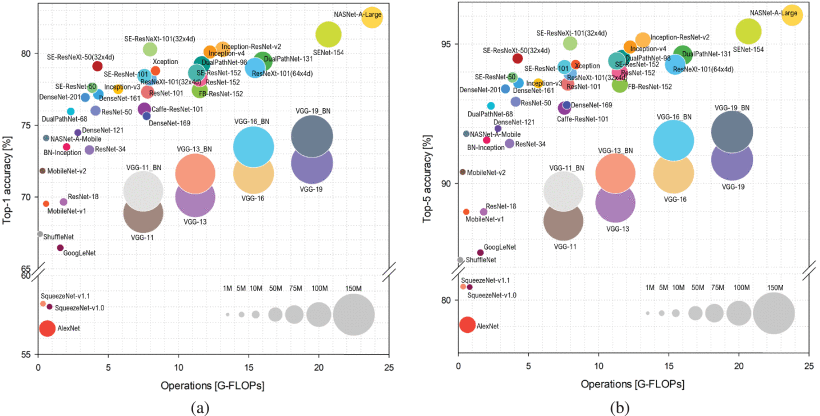

图5.2-1 常见Backbone的准确率/计算量[6]

可以看到，VGG拥有数十倍的参数量而准确率却远不如其它网络（如ResNet50）。但是这并不意味着DnCNN无法在性能受限的平台使用，通过替换Backbone就有可能大幅度降低计算需求，如目标检测算法YOLOv5就可以在智能手机上达到实时计算的性能，这得益于其高效的Focus-DarkNet。

## 6.结论*Conclusion*

当下，越来越多的用于智能产品的芯片（如ARM Cortex、RISC-V等）都会集成机器学习处理单元以进一步提升模型推理速度，毫无疑问，这将进一步推动这类算法的落地。事实上，深度学习早已成为计算机视觉领域的中流砥柱，无论是人脸识别、车载传感器，机器人，亦或是现如今智能手机中的“计算摄影”，到处都有深度学习的影子。

目前深度学习占据了感知领域的绝大多数（CV和NLP），对于智能系统来说，感知系统可以被认为是一种广义的“传感器”。比如，在过去，汽车想要感知特定的物体是不可能的，雷达不能直接在如此复杂（行车道路中）的情况下获得信息（正如巡航导弹会被热诱弹干扰一样）。诚然，通过特征工程（如K-近邻、SVM等）可以一定程度上进行模式识别，然而它们对于现实的非线性情况的表现都算不上好。而通过深度学习，摄像头可以直接捕获特定的目标（如实例分割、目标检测）以辅助其它传感器（如激光雷达等）或系统进行工作。这对自动驾驶、机器人等诸多领域提供了帮助。

然而，尽管它如此有效，现在却尚无人可以证明它为什么有效，也就是说，现在外人称呼的所谓"AI”领域，几乎没有什么“可解释性”可言。现行的模型几乎都以梯度下降作为优化方法，但人们却很难解释为什么一个如此简单的方法可以解决模型内部极度复杂的优化问题（尽管它确实是有效的）。不过，这些至少不影响你在智能手机上感叹景色的美妙，或者是在电商app上收到前一秒刚刚与他人讨论过的内容的商品信息。至于在更多领域的表现，现在亦有很多有重量级的工作，比如自动驾驶、机器人控制等，可以说未来可期。

## 参考文献*Reference*

[1] Karen Simonyan and Andrew Zisserman. Very Deep Convolutional Networks for Large-Scale Image Recognition.  *arXiv:1409.1556, *2014.

[2] Kai Zhang, Wangmeng Zuo, Yunjin Chen, Deyu Meng and LeiZhang. Beyond a Gaussian Denoiser: Residual Learning of Deep CNN for Image Denoising [J]. In *IEEE Transactions on Image Processing, *2017.

[3] Ian Goodfellow, Yoshua Bengio and Aaron Courville. Deep Learning [M]. Cambridge: The MIT Press, 2016.

[4] Kaiming He, Xiangyu Zhang, Shaoqing Ren and Jian Sun. Deep Residual Learning for Image Recognition[J]. In *Proceedings of the IEEE Conference on Computer Vision and Pattern Recognition (CVPR)*, 2016.

[5] Alexey Dosovitskiy, Lucas Beyer, Alexander Kolesnikov, Dirk Weissenborn, Xiaohua Zhai, Thomas Unterthiner, Mostafa Dehghani, Matthias Minderer, Georg Heigold, Sylvain Gelly, Jakob Uszkoreit and Neil Houlsby. An Image is Worth 16x16 Words: Transformers for Image Recognition at Scale [J]. In *International Conference on Learning Representations (ICLR), *2021.

[6] Simone Bianco, Remi Cadene, Luigi Celona and Paolo Napoletano. Benchmark Analysis of Representative Deep Neural Network Architectures[J]. In *IEEE Access, *2018.